
path2signal="C:\Users\amitp25\Downloads\mldl_course_files\RobotProject\robotdata"

path2signal = "C:\Users\amitp25\Downloads\mldl_course_files\RobotProject\robotdata"

robods=signalDatastore(path2signal,"SignalVariableNames",["front","left"],"ReadOutputOrientation","row")

robods =   signalDatastore with properties:

                       Files:{
                             ' ...\amitp25\Downloads\mldl_course_files\RobotProject\robotdata\turn1.csv';
                             ' ...\amitp25\Downloads\mldl_course_files\RobotProject\robotdata\turn2.csv';
                             ' ...\amitp25\Downloads\mldl_course_files\RobotProject\robotdata\turn3.csv'
                              ... and 1 more
                             }
                     Folders: {'C:\Users\amitp25\Downloads\mldl_course_files\RobotProject\robotdata'}
    AlternateFileSystemRoots: [0×0 string]
                    ReadSize: 1
         SignalVariableNames: ["front"    "left"]
       ReadOutputOrientation: "row"


transds=transform(robods,@prepsig)

transds =   TransformedDatastore with properties:

      UnderlyingDatastores: {signalDatastore}
    SupportedOutputFormats: ["txt"    "csv"    "xlsx"    "xls"    "parquet"    "parq"    "png"    "jpg"    "jpeg"    "tif"    "tiff"    "wav"    "flac"    "ogg"    "mp4"    "m4a"]
                Transforms: {@prepsig}
               IncludeInfo: 0


sigdata=readall(transds)

sigdata = 4×1 cell array
    {2×1418 double}
    {2×1547 double}
    {2×1138 double}
    {2×1353 double}


labelds=signalDatastore(path2signal,"SignalVariableNames","direction")

labelds =   signalDatastore with properties:

                       Files:{
                             ' ...\amitp25\Downloads\mldl_course_files\RobotProject\robotdata\turn1.csv';
                             ' ...\amitp25\Downloads\mldl_course_files\RobotProject\robotdata\turn2.csv';
                             ' ...\amitp25\Downloads\mldl_course_files\RobotProject\robotdata\turn3.csv'
                              ... and 1 more
                             }
                     Folders: {'C:\Users\amitp25\Downloads\mldl_course_files\RobotProject\robotdata'}
    AlternateFileSystemRoots: [0×0 string]
                    ReadSize: 1
         SignalVariableNames: "direction"
       ReadOutputOrientation: "column"


transds=transform(labelds,@preplabel)

transds =   TransformedDatastore with properties:

      UnderlyingDatastores: {signalDatastore}
    SupportedOutputFormats: ["txt"    "csv"    "xlsx"    "xls"    "parquet"    "parq"    "png"    "jpg"    "jpeg"    "tif"    "tiff"    "wav"    "flac"    "ogg"    "mp4"    "m4a"]
                Transforms: {@preplabel}
               IncludeInfo: 0


label=readall(transds)

label = 4×1 cell array
    {1×1418 categorical}
    {1×1547 categorical}
    {1×1138 categorical}
    {1×1353 categorical}


traindata=sigdata(1:3)

traindata = 3×1 cell array
    {2×1418 double}
    {2×1547 double}
    {2×1138 double}


trainlabels=label(1:3)

trainlabels = 3×1 cell array
    {1×1418 categorical}
    {1×1547 categorical}
    {1×1138 categorical}


valdata=sigdata{4}

valdata =     1.5150    1.5050    1.4940    1.4840    1.4730    1.4640    1.4540    1.4440    1.4340    1.4240    1.4150    1.4060    1.3970    1.3870    1.3770    1.3660    1.3540    1.3400    1.3260    1.3110    1.2980    1.2790    1.2620    1.2450    1.2270    1.2090    1.1920    1.1740    1.1560    1.1410    1.1220    1.1030    1.0840    1.0650    1.0430    1.0240    1.0060    0.9880    0.9700    0.9520    0.9330    0.9150    0.8970    0.8780    0.8600    0.8430    0.8250    0.8090    0.7940    0.7850
    0.4760    0.4780    0.4790    0.4810    0.4820    0.4840    0.4860    0.4880    0.4900    0.4920    0.4940    0.4970    0.4990    0.5020    0.5050    0.5080    0.5120    0.5170    0.5230    0.5280    0.5340    0.5410    0.5490    0.5560    0.5650    0.5710    0.5790    0.5870    0.5950    0.6030    0.6110    0.6190    0.6270    0.6360    0.6450    0.6510    0.6620    0.6700    0.6780    0.6870    0.6960    0.7050    0.7140    0.7220    0.7300    0.7380    0.7460    0.7530    0.759

vallabels=label{4}

vallabels = 1×1353 categorical array
  Columns 1 through 486

     Slight-Right-Turn      Slight-Right-Turn      Slight-Right-Turn      Slight-Right-Turn      Slight-Right-Turn      Slight-Right-Turn      Slight-Right-Turn      Slight-Right-Turn      Slight-Right-Turn      Slight-Right-Turn      Slight-Right-Turn      Move-Forward      Move-Forward      Move-Forward      Move-Forward      Move-Forward      Move-Forward      Move-Forward      Move-Forward      Move-Forward      Move-Forward      Move-Forward      Move-Forward      Move-Forward      Move-Forward      Move-Forward      Move-Forward      Move-Forward      Move-Forward      Move-Forward      Move-Forward      Move-Forward      Move-Forward      Move-Forward      Move-Forward      Move-Forward      Move-Forward      Move-Forward      Move-Forward      Move-Forward      Move-Forward      Move-Forward      Sharp-Right-Turn      Sharp-Right-Turn      Sharp-Right-Turn      Sharp-Right-Turn      Sharp-Right-Turn      Sharp-Right-

Network Architecture

num_classes=4;
num_hidden_units=100;
inputsize=2;
layers=[...
    sequenceInputLayer(inputsize)
    bilstmLayer(num_hidden_units,"OutputMode","sequence")
    fullyConnectedLayer(num_classes)
    softmaxLayer
    classificationLayer];
    
options = trainingOptions("adam", ...
    "ValidationData",{valdata vallabels},...
    "GradientThreshold",1, ...
    "MaxEpochs",1000, ...
    "SequenceLength","longest", ...
    "InitialLearnRate", 0.001);


net=trainNetwork(traindata,trainlabels,layers,options)

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:02 |       46.24% |       42.20% |       1.2075 |       1.3112 |          0.0010 |
|      50 |          50 |       00:01:13 |       65.85% |       79.08% |       0.5707 |       0.5777 |          0.0010 |
|     100 |         100 |       00:02:24 |       72.81% |       86.33% |       0.4066 |       0.4132 |          0.0010 |
|     150 |         150 |       00:03:35 |       77.87% |       86.25% |       0.2775 |       0.3455 |          0.0010 |
|     20

net =   SeriesNetwork with properties:

         Layers: [5×1 nnet.cnn.layer.Layer]
     InputNames: {'sequenceinput'}
    OutputNames: {'classoutput'}


pred_data=classify(net,valdata)

pred_data = 1×1353 categorical array
  Columns 1 through 481

     Slight-Right-Turn      Slight-Right-Turn      Slight-Right-Turn      Slight-Right-Turn      Slight-Right-Turn      Slight-Right-Turn      Slight-Right-Turn      Slight-Right-Turn      Slight-Right-Turn      Slight-Right-Turn      Slight-Right-Turn      Slight-Right-Turn      Sharp-Right-Turn      Sharp-Right-Turn      Sharp-Right-Turn      Sharp-Right-Turn      Slight-Right-Turn      Slight-Right-Turn      Slight-Right-Turn      Slight-Right-Turn      Slight-Right-Turn      Slight-Right-Turn      Slight-Right-Turn      Slight-Right-Turn      Slight-Right-Turn      Slight-Right-Turn      Slight-Right-Turn      Slight-Right-Turn      Move-Forward      Move-Forward      Move-Forward      Move-Forward      Move-Forward      Move-Forward      Move-Forward      Move-Forward      Move-Forward      Sharp-Right-Turn      Sharp-Right-Turn      Sharp-Right-Turn      Sharp-Right-Turn      Sharp-Right-Turn      Sharp-Right-Turn     

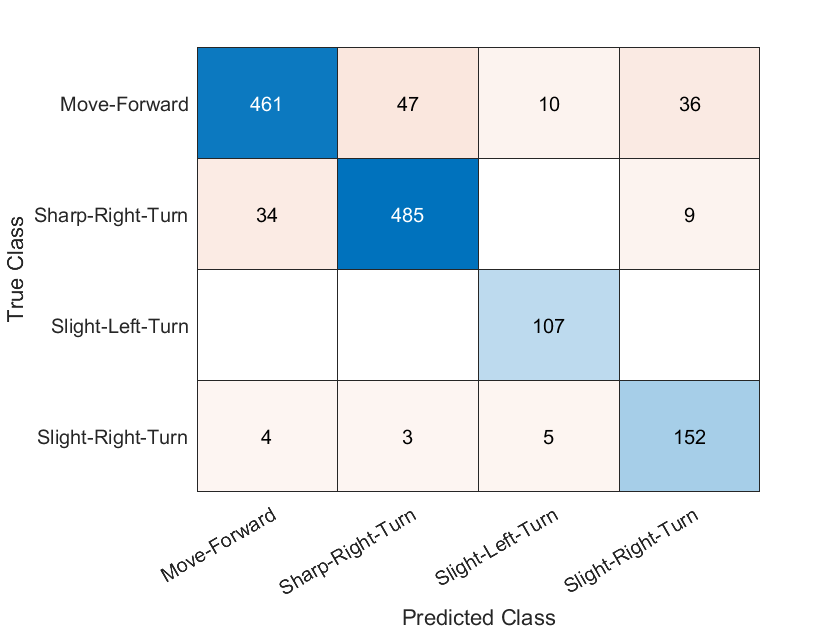

confusionchart(vallabels,pred_data)

function [labelout] = preplabel(label)
    labelcat = categorical(label);
    labeltranspose = labelcat';
    labelout = {labeltranspose};
end
function sigout = prepsig(sig)
    sigmatrix = cell2mat(sig);
    sigtranspose = sigmatrix';
    sigout = {sigtranspose};
end